%清空变量
warning off
close all
clear,clc
% 设定当前图像的背景为白色
set(gcf, 'color', 'w');
% 获取当前图像对象中所有的子对象
allAxesInFigure = findall(gcf, 'type', 'axes');
% 将所有子对象的背景设为白色
set(allAxesInFigure,'color','w');

x_axis = linspace(42.21595, 3288.67847, 2048) % 拉曼峰移

x_axis = 	1.0e+03 *

    0.0422    0.0438    0.0454    0.0470    0.0486    0.0501    0.0517    0.0533    0.0549    0.0565    0.0581    0.0597    0.0612    0.0628    0.0644    0.0660    0.0676    0.0692    0.0708    0.0723    0.0739    0.0755    0.0771    0.0787    0.0803    0.0819    0.0835    0.0850    0.0866    0.0882    0.0898    0.0914    0.0930    0.0946    0.0961    0.0977    0.0993    0.1009    0.1025    0.1041    0.1057    0.1072    0.1088    0.1104    0.1120    0.1136    0.1152    0.1168    0.1183    0.1199


data_all = readtable('D:\桌面\论文材料\RAMAN实验\之前的数据\第二次光谱数据.xlsx');
data_all = removevars(data_all, {'Var1'});
data_all = table2array(data_all(2:end,:))

data_all = 	1.0e+03 *

    0.0019    0.0031    0.0032    0.0006    0.0027    0.0046    0.0003    0.0033    0.0039    0.0032    0.0017    0.0043    0.0053    0.0067    0.0078    0.0095    0.0138    0.0284    0.0514    0.1016    0.1963    0.3846    0.6244    0.8068    0.9113    0.9351    0.9298    0.9273    0.9668    0.9895    0.9448    0.8820    0.8578    0.8576    0.8467    0.8414    0.8422    0.8223    0.7982    0.7795    0.7616    0.7417    0.7370    0.7447    0.7455    0.7181    0.6964    0.6910    0.6860    0.6799
   -0.0004    0.0032    0.0025    0.0039    0.0013    0.0025    0.0033    0.0016    0.0017    0.0035    0.0034    0.0027    0.0028    0.0053    0.0065    0.0103    0.0159    0.0268    0.0530    0.1017    0.2070    0.4006    0.6451    0.8435    0.9433    0.9731    0.9615    0.9667    1.0008    1.0274    0.9832    0.9119    0.8913    0.8991    0.8865    0.8791    0.8725    0.8553    0.8293    0.8150    0.7959    0.7692    0.7654    0.7790    0.7731    0.7481    0.7317    0.

% %标签扩大
% y_labe = data_all(:,1:5);
% y_labelagum = zeros(size(y_labe,1)*4, size(y_labe,2));
% 
% for i = 1:size(y_labe,1)
%     for n = 1:4
%         y_labelagum((i-1)*4+n,:) = y_labe(i,:)    
%     end    
% end

x=int16(linspace(10,600,26))

x = 1×26 int16 行向量
    10    34    57    81   104   128   152   175   199   222   246   270   293   317   340   364   388   411   435   458   482   506   529   553   576   600


y=data_all(x,1:end)

y = 	1.0e+03 *

    0.0036    0.0030    0.0022    0.0017    0.0023    0.0002    0.0031    0.0019    0.0031    0.0033    0.0040    0.0028    0.0034    0.0060    0.0061    0.0070    0.0154    0.0283    0.0573    0.1017    0.2065    0.3998    0.6434    0.8420    0.9357    0.9615    0.9578    0.9520    0.9899    1.0150    0.9736    0.9066    0.8836    0.8860    0.8759    0.8665    0.8640    0.8467    0.8167    0.8003    0.7879    0.7585    0.7513    0.7678    0.7609    0.7359    0.7177    0.7025    0.6973    0.6992
    0.0006   -0.0001   -0.0005    0.0012    0.0006    0.0023    0.0032    0.0021    0.0039    0.0033    0.0017    0.0065    0.0046    0.0045    0.0052    0.0079    0.0150    0.0296    0.0532    0.1038    0.2092    0.4069    0.6476    0.8469    0.9463    0.9700    0.9685    0.9657    1.0027    1.0294    0.9872    0.9100    0.8903    0.8960    0.8789    0.8748    0.8706    0.8545    0.8262    0.8095    0.7933    0.7655    0.7588    0.7749    0.7676    0.7436    0.7270    0.7144   

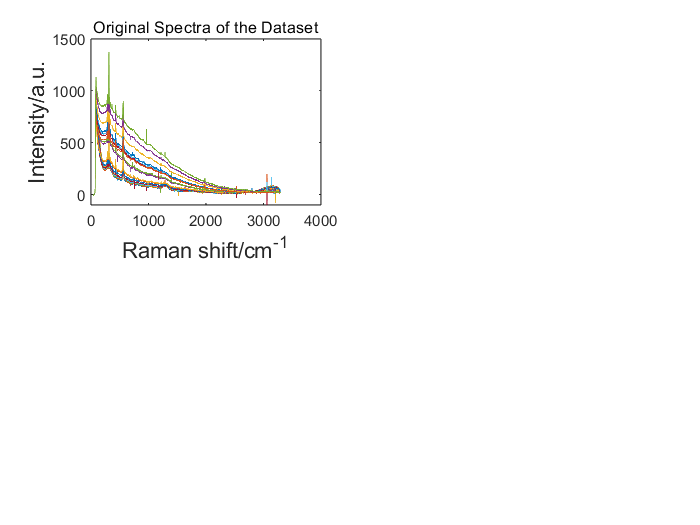

figure(1)
hold on;
subplot(2,2,1);
plot(x_axis,y);
title("Original Spectra of the Dataset",'fontsize',13)
xlabel('Raman shift/cm^{-1}','fontsize',13)
ylabel('Intensity/a.u.','fontsize',13)

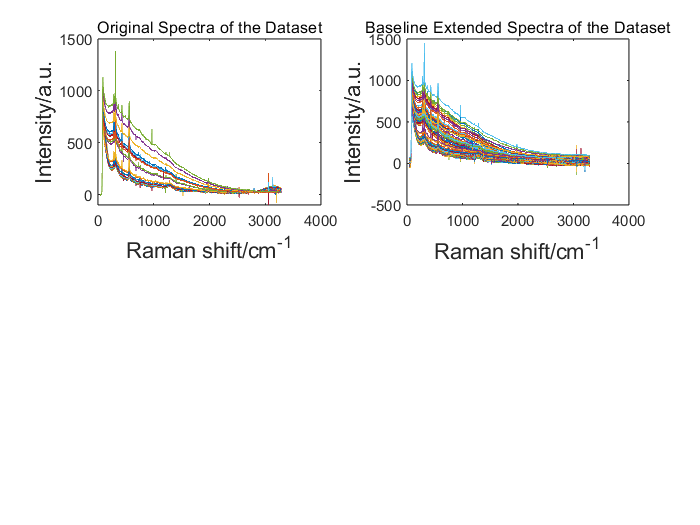

k_list = [-1, -2, 0, 3]; % 四种基线斜率

% 取出原始数据y，并扩充四倍数据集
%y = data_all(:, 6:end);
y_extend = zeros(size(y,1)*4, size(y,2));

% 施加不同基线斜率，扩充数据集
for i = 1:4
    k = k_list(i);
    for j = 1:size(y,1)
        y_extend((i-1)*size(y,1)+j,:) = y(j,:) + k*(j-1)';
    end
end

% 画出扩充后的数据集
subplot(2,2,2);
plot(x_axis, y_extend);
title("Baseline Extended Spectra of the Dataset",'fontsize',13)
xlabel('Raman shift/cm^{-1}','fontsize',13)
ylabel('Intensity/a.u.','fontsize',13)

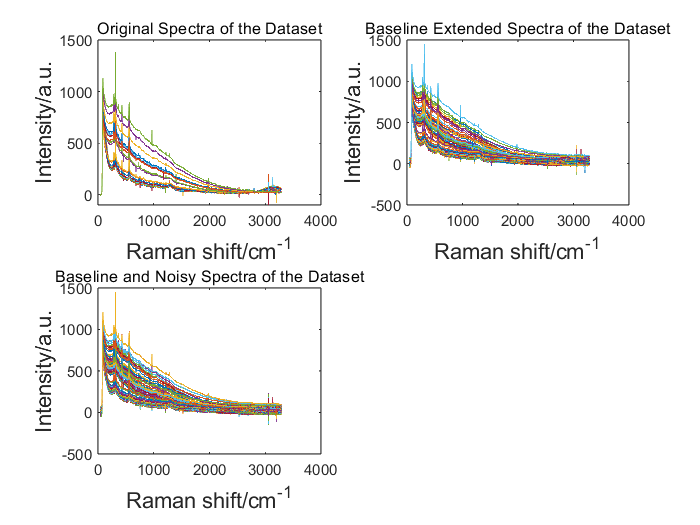

% 添加高斯白噪声，并规模扩大四倍
mu = 0; % 均值为0
sigma_list = [0.01, 0.3, 0.5, 0.7]; % 标准差列表
y_noisy = zeros(size(y,1)*4, size(y,2)); % 存储添加噪声后的矩阵

for j = 1:size(y_extend,1) % 遍历每一行
    row = y_extend(j,:);
    for i = 1:4 % 遍历标准差列表
        sigma = sigma_list(i);
        % 添加当前标准差的高斯噪声
        noise = normrnd(mu, sigma, size(row));
        row_noisy = row + noise;
        % 将添加噪声后的数据存储到矩阵y_noisy中
        idx = (j-1)*4 + i;
        y_noisy(idx,:) = row_noisy;
    end
end

% 画出添加噪声后的数据集
subplot(2,2,3);
plot(x_axis, y_noisy);
title("Baseline and Noisy Spectra of the Dataset",'fontsize',13)
xlabel('Raman shift/cm^{-1}','fontsize',13)
ylabel('Intensity/a.u.','fontsize',13)

% 
% % 对数据进行扩充
% n = size(y_noisy, 2); % 列数
% num_groups = size(y_noisy, 1) / 16; % 组数
% m = num_groups * 32; % 扩充后的行数
% x_new = linspace(x_axis(1), x_axis(end), n);
% y_expanded = zeros(m, n); % 初始化扩充后的数据
% 
% for i = 1:num_groups
%     start_idx = (i - 1) * 16 + 1; % 计算当前组的起始索引
%     end_idx = start_idx + 15; % 计算当前组的结束索引
%     data_class = y_noisy(start_idx:end_idx, :); % 取出当前组的数据
%     coef = rand(32, 16); % 生成32行16列的随机系数矩阵
%     coef = coef ./ sum(coef, 2); % 将各行的系数归一化，保证每行系数之和为1
%     
%     % 对16行数据按元素乘以系数
%     expanded_rows = zeros(32, n); % 初始化当前组扩充后的数据
%     for j = 1:32
%         cur_coef = coef(j,: ); % 取出当前行的系数
%         % 将当前行的数据乘以当前行的系数，并累加到扩充后的当前组数据中
%         expanded_rows(j, :) =sum(data_class.*coef(j,: )',1) 
%     end
%     
%     % 将扩充后的当前组数据存储到扩充后的数据中
%     start_row = (i - 1) * 32 + 1; % 计算当前组扩充后的起始行索引
%     end_row = start_row + 31; % 计算当前组扩充后的结束行索引
%     y_expanded(start_row:end_row, :) = expanded_rows;
% end
% 
% % 绘制扩充后的数据曲线
% plot(x_new, y_expanded);
% title('Baseline and Noisy Spectra of the Dataset with Expansion');
% xlabel('Raman shift/cm^{-1}');
% ylabel('Intensity/a.u.');

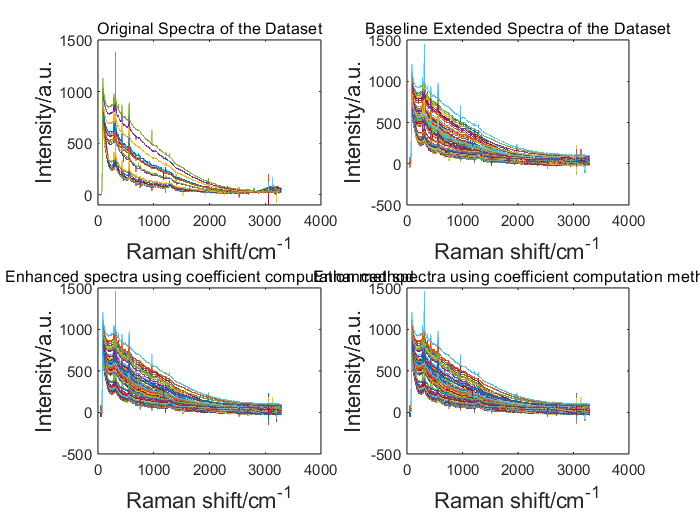

k_list = [0.001, 0.005]; % 两种种基线斜率

% 取出原始数据y，并扩充两倍数据集
y = y_noisy;
y_interp = zeros(size(y,1)*2, size(y,2));

% 施加不同基线斜率，扩充数据集
for i = 1:2
    k = k_list(i);
    for j = 1:size(y,1)
       y_interp((i-1)*size(y,1)+j,:) = y(j,:) + k*(j-1)';
    end
end

% 画出扩充后的数据集
subplot(2,2,4);
plot(x_axis, y_interp);
title("Enhanced spectra using coefficient computation method",'fontsize',13)
xlabel('Raman shift/cm^{-1}','fontsize',13)
ylabel('Intensity/a.u.','fontsize',13)

% 输出表
y_merge = horzcat(y_labelagum,  y_noisy);
xlswrite('D:\桌面\论文材料\RAMAN第二次实验\离线值光谱数据增强.xlsx', y_merge);